%求解小椭圆储油罐变位前的v-h公式
syms y a b h L
v1=L*int(2*a*sqrt(1-(y-b)^2)/b^2,y,0,h);
v=simplify(v1)

$$v = \frac{2\,L\,a\,\int_{0}^{h}\sqrt{1-{\left(b-y\right)}^{2}}\mathrm{d}y}{b^{2}}$$

%根据v-h公式求解罐容表
h=0:0.01:1.2;
v=5/9*(-13083/10000*(18/25-3/5*h).^(1/2).*h+4361/2000*(18/25-3/5*h).^(1/2).*h.^2+39249/125000*15^(1/2)*asin(1/6*30^(1/2)*h.^(1/2)).*h.^(1/2))./h.^(1/2)*15^(1/2)

v =        NaN    0.0053    0.0149    0.0274    0.0420    0.0586    0.0768    0.0966    0.1177    0.1400    0.1636    0.1882    0.2139    0.2405    0.2681    0.2965    0.3258    0.3558    0.3866    0.4181    0.4503    0.4831    0.5165    0.5506    0.5852    0.6204    0.6560    0.6922    0.7289    0.7660    0.8035    0.8415    0.8799    0.9186    0.9578    0.9972    1.0371    1.0772    1.1176    1.1583    1.1993    1.2405    1.2820    1.3237    1.3657    1.4078    1.4501    1.4926    1.5353    1.5781


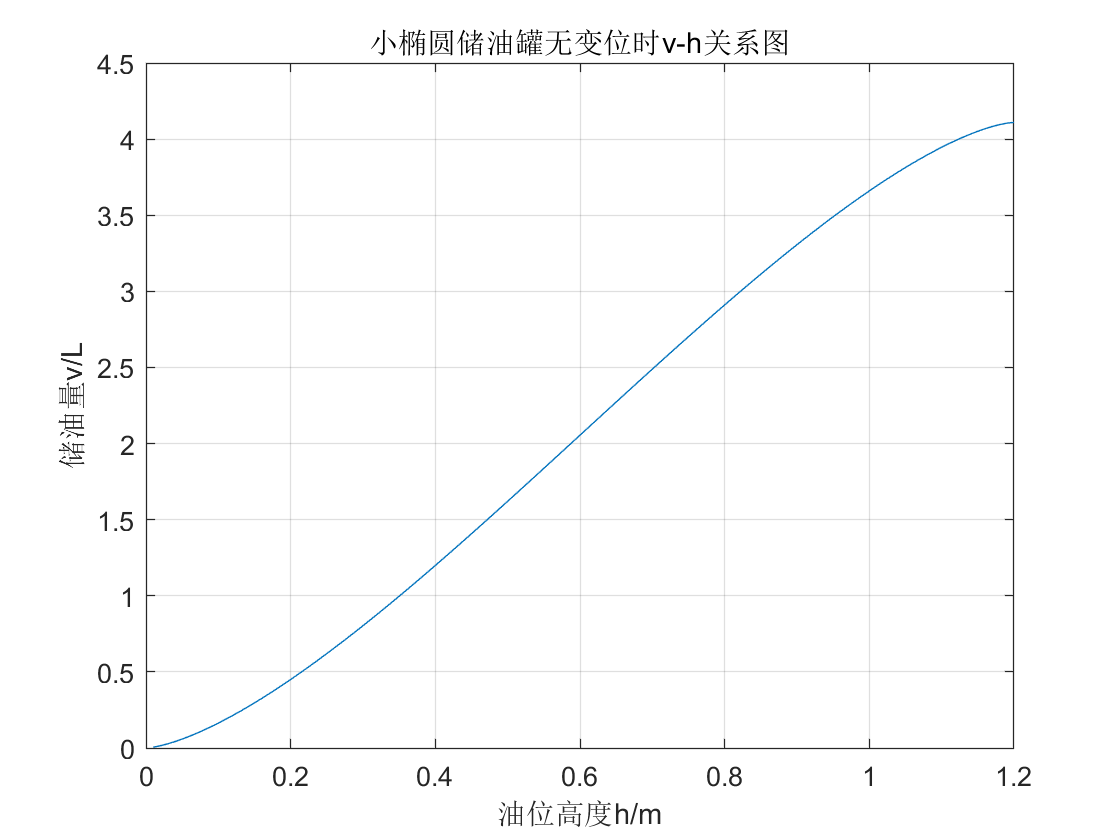

plot(h,v)
grid on
axis([0 1.2 0 4.5])
xlabel('油位高度h/m')
ylabel('储油量V/L')
title('小椭圆储油罐无变位时V-h关系图')

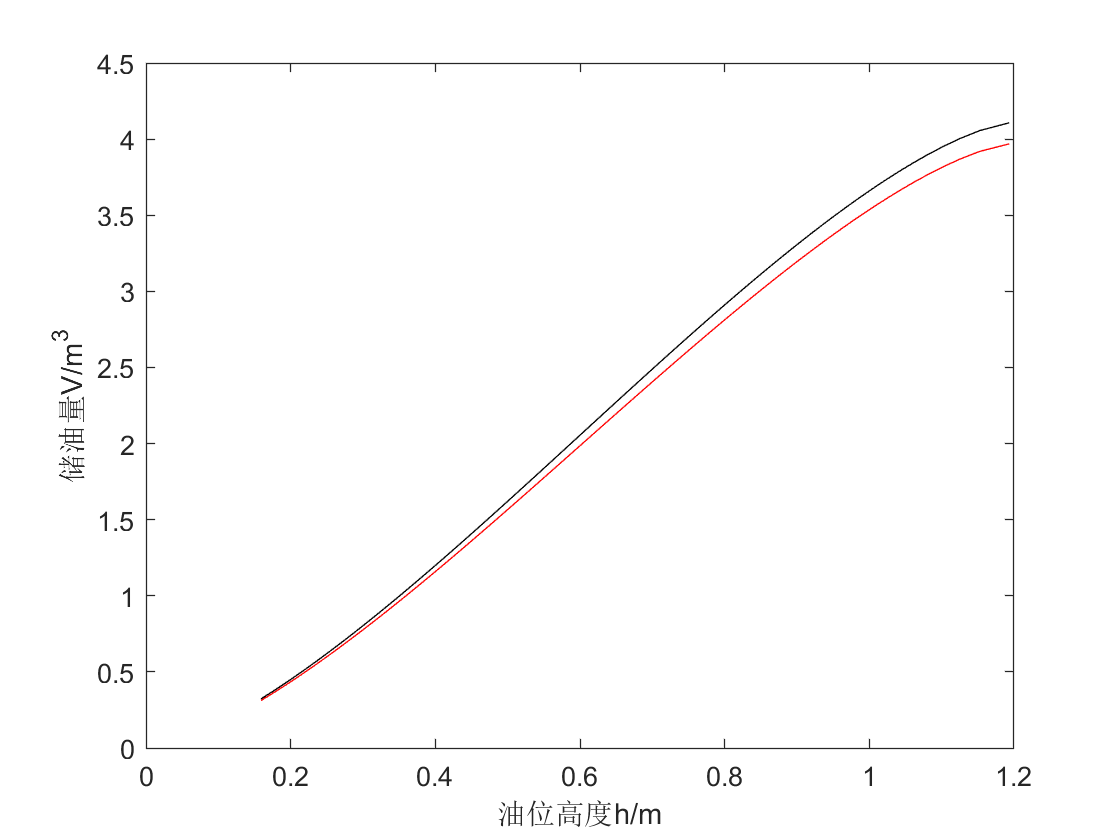

%??测量值和理论值数据对比
v1=[50:50:2050 ...
    2053.83 2103.83 2105.06 2155.06 2205.06 2255.06 2305.06 2355.06 2404.98 ...
    2406.83:50:2906.83 2906.91:50:3706.91]; %无变位累计进油量/L
v1=(262+v1)/1000;
h=[159.02 176.14 192.59 208.50 223.93 238.97 253.66 268.04 282.16 296.03 ...
309.69 323.15 336.44 349.57 362.56 375.42 388.16 400.79 413.32 425.76   ...
438.12 450.40 462.62 474.78 486.89 498.95 510.97 522.95 534.90 546.82   ...
558.72 570.61 582.48 594.35 606.22 618.09 629.96 641.85 653.75 665.67   ...
677.63 678.54 690.53 690.82 702.85 714.91 727.03 739.19 751.42 763.70   ...
764.16 776.53 788.99 801.54 814.19 826.95 839.83 852.84 866.00 879.32   ...
892.82 892.84 906.53 920.45 934.61 949.05 963.80 978.91 994.43 1010.43  ...
1026.99 1044.25 1062.37 1081.59 1102.33 1125.32 1152.36 1193.49]';   %无变位油位高度/mm
h=h/1000;
v2=5/9*(-13083/10000*(18/25-3/5*h).^(1/2).*h+4361/2000*(18/25-3/5*h).^(1/2).*h.^2+39249/125000*15^(1/2)*asin(1/6*30^(1/2)*h.^(1/2)).*h.^(1/2))./h.^(1/2)*15^(1/2);
plot(h,v1,'r',h,v2,'k','markersize',4)
xlabel('油位高度h/m')
ylabel('储油量V/m^3')

v1./v2

ans =     0.9663    1.1212    1.2760    1.4309    1.5857    1.7406    1.8954    2.0503    2.2051    2.3600    2.5148    2.6697    2.8246    2.9794    3.1343    3.2891    3.4440    3.5988    3.7537    3.9085    4.0634    4.2183    4.3731    4.5280    4.6828    4.8377    4.9925    5.1474    5.3022    5.4571    5.6119    5.7668    5.9217    6.0765    6.2314    6.3862    6.5411    6.6959    6.8508    7.0056    7.1605    7.1724    7.3272    7.3310    7.4859    7.6407    7.7956    7.9504    8.1053    8.2599
    0.8328    0.9663    1.0997    1.2332    1.3667    1.5001    1.6336    1.7671    1.9005    2.0340    2.1675    2.3009    2.4344    2.5678    2.7013    2.8348    2.9682    3.1017    3.2352    3.3686    3.5021    3.6356    3.7690    3.9025    4.0359    4.1694    4.3029    4.4363    4.5698    4.7033    4.8367    4.9702    5.1037    5.2371    5.3706    5.5041    5.6375    5.7710    5.9044    6.0379    6.1714    6.1816    6.3151    6.3183    6.4518    6.5853    6.7187    6.8522    6.9857   

%变位后理论值和实际值相比较
v1=[
1.01 1.0583 1.118 1.1675 1.2221 1.2791 1.3274 1.3825 1.4335 1.4849 1.536 1.5918
1.6451 1.6973 1.7498 1.7966 1.8487 1.9 1.9527 1.9991 2.0526 2.1032 2.1484 2.2022
2.2527 2.3037 2.3521 2.4027 2.4522 2.4978 2.5486 2.5995 2.6446 2.6962 2.7488
2.7988 2.8472 2.8958 2.942 2.9925 3.0441 3.0896 3.1408 3.1897 3.234 3.2841
3.3345 3.379 3.4235 3.4731 3.5176 3.5694 3.5732];
v2=[0.9629 1.0129 1.0629 1.1129 1.1629 1.2129 1.2629 1.3128 1.3628 1.4127 1.4627
1.5127 1.5627 1.6127 1.6627 1.7127 1.7627 1.8127 1.8627 1.9127 1.9627 2.0127
2.0627 2.1127 2.1627 2.2127 2.2627 2.3127 2.3627 2.4127 2.4627 2.5127 2.5627
2.6127 2.6627 2.7127 2.7627 2.8127 2.8627 2.9127 2.9627 3.0127 3.0627 3.1127
3.1627 3.2127 3.2627 3.3127 3.3627 3.4127 3.4627 3.5127 3.5147 ];
s1=v1-v2;
s=(v1-v2)./v1;
h=[411.29 423.45 438.33 450.54 463.90 477.74 489.37 502.56 514.69 526.84 538.88
551.96 564.40 576.56 588.74 599.56 611.62 623.44 635.58 646.28 658.59 670.22
680.63 693.03 704.67 716.45 727.66 739.39 750.90 761.55 773.43 785.39 796.04
808.27 820.80 832.80 844.47 856.29 867.60 880.06 892.92 904.34 917.34 929.90
941.42 954.60 968.09 980.14 992.41 1006.34 1019.07 1034.24 1035.36];
h=h/1000;
plot(h,s)
grid on
24
xlabel('油位高度/m')
ylabel('储油量V/立方米')
figure(2)
plot(h,s1)
grid on
xlabel('油位高度/m')
ylabel('储油量/m³')
figure(3)
plot(h,v1,'k*',h,v2,'r')
grid on
xlabel('油位高度/m')
ylabel('储油量/m³')

clear all
syms y h
va=2*int(0.89*sqrt(1-y^2/0.6^2)*((h+0.4*0.0717-0.6+y)/0.0717),y,(0.6-(h/0.0
717+0.4)*0.0717),0.6);
for h=0:0.0005:2.05*tan(4.1*pi/180)
r=eval(va);
hold on
plot(h,r)
grid on
end
axis([0 1.4 0 4.5])
syms h
v1=2*int(((h+0.4*0.0717)-y)/0.0717*(0.89*(1-((y-0.6)/0.6)^2)^0.5),y,h,(h+0.
4*0.0717));
v=0.89*0.6*2.45*((h-0.6)/0.36*(h*(1.2-h))^0.5+asin(h/0.6-1)+pi/2);
v2=2*int((2.45-((h+0.4*0.0717)-y)/0.0717)*(0.89*(1-((y-0.6)/0.6)^2)^0.5),y,
(h-2.05*0.0717),h);
v=v1+v-v2;
for h=2.05*tan(4.1*pi/180):0.005:1.2-0.4*tan(4.1*pi/180)
r=eval(v);
hold on
plot(h,r,'r.')
grid on
end
syms y h
va=4.1101-2*int(0.89*sqrt(1-y^2/0.6^2)*((1.2-h+2.05*0.0717-0.6+y)/0.0717),y
,(0.6-((1.2-h)/0.0717+2.05)*0.0717),0.6);
for h=1.2-0.4*tan(4.1*pi/180):0.0001:1.2
r=eval(va);
hold on
plot(h,r,'g.')
25
grid on
end
h=0:0.01:1.2;
v=5/9*(-13083/10000*(18/25-3/5*h).^(1/2).*h+4361/2000*(18/25-3/5*h).^(1/2).
*h.^2+39249/125000*15^(1/2)*asin(1/6*30^(1/2)*h.^(1/2)).*h.^(1/2))./h.^(1/2
)*15^(1/2);
plot(h,v)
xlabel('油位高度/m')
ylabel('储油量/m³')
gtext('变位前')
gtext('变化后')

无效表达式。调用函数或对变量进行索引时，请使用圆括号。否则，请检查不匹配的分隔符。

%变位前后理论值相比较
clear all
syms y h
va=2*int(0.89*sqrt(1-y^2/0.6^2)*((h+0.4*0.0717-0.6+y)/0.0717),y,(0.6-(h/0.0
717+0.4)*0.0717),0.6);
for h=0:0.0005:2.05*tan(4.1*pi/180)
r=eval(va);
hold on
plot(h,r)
grid on
end
axis([0 1.4 0 4.5])
syms h
v1=2*int(((h+0.4*0.0717)-y)/0.0717*(0.89*(1-((y-0.6)/0.6)^2)^0.5),y,h,(h+0.
4*0.0717));
v=0.89*0.6*2.45*((h-0.6)/0.36*(h*(1.2-h))^0.5+asin(h/0.6-1)+pi/2);
v2=2*int((2.45-((h+0.4*0.0717)-y)/0.0717)*(0.89*(1-((y-0.6)/0.6)^2)^0.5),y,
(h-2.05*0.0717),h);
v=v1+v-v2;
for h=2.05*tan(4.1*pi/180):0.005:1.2-0.4*tan(4.1*pi/180)
r=eval(v);
hold on
plot(h,r,'r.')
grid on
end
syms y h
va=4.1101-2*int(0.89*sqrt(1-y^2/0.6^2)*((1.2-h+2.05*0.0717-0.6+y)/0.0717),y
,(0.6-((1.2-h)/0.0717+2.05)*0.0717),0.6);
for h=1.2-0.4*tan(4.1*pi/180):0.0001:1.2
r=eval(va);
hold on
plot(h,r,'g.')
26
grid on
end
h=0:0.01:1.2;
v=5/9*(-13083/10000*(18/25-3/5*h).^(1/2).*h+4361/2000*(18/25-3/5*h).^(1/2).
*h.^2+39249/125000*15^(1/2)*asin(1/6*30^(1/2)*h.^(1/2)).*h.^(1/2))./h.^(1/2
)*15^(1/2)
plot(h,v)

%2.2
v1=[5.4400 7.3156 9.3777 11.6020 13.9601 16.4359 19.0078 21.6554 24.3670 27.1208 29.9065
32.7028 35.4998 38.2793 41.0227 43.7196 46.3481 48.8963 51.3434 53.6675 55.8495 57.8667
59.6864 61.2643 ];
v01=[0.0202 0.0270 0.0399 0.0405 0.0466 0.0520 0.0566 0.0603 0.0630 0.0646 0.0651 0.0645
0.0629 0.0602 0.0565 0.0519 0.0466 0.0406 0.0342 0 .0276 0.0210 0.0148 0.0091
0.0045 0.00019 ];
v02=flipud(v01); v0=v01-v02;
v0(1)=[]; v2=v1+v0;
hold on
plot(v1,'r*')
plot(v2)
grid on

%估计参数α和β
detav=243.85/1000; minv=100;
h1=2485.73/1000;h2=2474.4/1000;
L=8;R=1.5;R0=1.625;H=1;l=2;
syms y
for a=linspace(0.001,4.5*pi/180,20);
for b=linspace(0.001,4.5*pi/180,20);
hb=h1;
v1=-6*cos(b)*(9-9*cos(b)^2+...+2*cos(b)*hb))^(1/2);
hb=h2;
v2=-6*cos(b)*(9-9*cos(b)^2+...+2*cos(b)*hb))^(1/2);
mv=v1-v2;
if minv>abs(mv-detav)
minv=abs(mv-detav);
aa=a;bb=b;
end
end
end
aa bb minv

%最小二乘拟合
syms hb a b
s=0;vh=zeros(1,10);aa=0;bb=0;
mins=100000;
v1=[309.66 249.73 186.43 231.42 297.79 109.19 162.87 328.5 166.13 237.66 ]'/1000;
h1=[11.34 9.20 6.84 8.40 10.87 3.99 5.95 11.92 6.03 8.59 ]'/1000;
vh1=-1/3000000000000000*(2*(22500000000- 9375-2137*cos(b)+37500*tan(a)))^(1/2);
（表达式太长，部分省略）
for a=linspace(0,0.1745,10)
for b=linspace(0,0.1745,10)
vh(1)=eval(vh1)
vh(2)=eval(vh2);
vh(3)=eval(vh3);
vh(4)=eval(vh4);
vh(5)=eval(vh5);
vh(6)=eval(vh6);
vh(7)=eval(vh7);
vh(8)=eval(vh8);
vh(9)=eval(vh9);
vh(10)=eval(vh10);
for i=1:10
s=s+(v1(i)-vh(i))^2
end
if s<mins
mins=s;
aa=a;
bb=b;
end
end
end
aa,bb

%综合考虑纵向清晰和横向偏转
syms x y %区域1
L=8;R=1.5;R0=1.625;H=1;l=2;a=0.0377;b=0.0785;
vh1=2*int((y-R+R*(1-cos(b))+l*tan(a))/tan(a)*(R^2-y^2)^0.5,R-R*(1-cos(b))-l*tan(a),R)
r=(R0^2-(x-R)^2)^0.5
vh2=int(r^2*acos((R0-H)/r)-((r^2-(R0-H)^2)^0.5)*(R0-H),x,0,R*(1-cos(b))+l*tan(a))
vh=vh1+vh2;
eval(vh)
syms x y %区域2
L=8;R=1.5;R0=1.625;H=1;l=2;a=0.0377;b=0.0785;
hb2max=((L-l)*tan(a)-R*(1-cos(b)))/cos(b);
28
hb=0.2224;
h=R-(R-hb)*cos(b);
vh1=2*int((y-R+h+l*tan(a))/tan(a)*(R^2-y^2)^0.5,y,R-h-l*tan(a),R);
r=(R0^2-(x-R)^2)^0.5;
vh2=int(r^2*acos((R0-H)/r)-((r^2-(R0-H)^2)^0.5)*(R0-H),x,0,h+l*tan(a));
vh=vh1+vh2;
eval(vh)
syms x y %区域3
L=8;R=1.5;R0=1.625;H=1;l=2;a=0.0377;b=0.0785;
hb=2.93;
h=R-(R-hb)*cos(b);
vh1=2*L*int((R^2-(y-R)^2)^0.5,y,0,h);
vh11=2*int((-y+h+l*tan(a))/tan(a)*(R^2-(y-R)^2)^0.5,y,h,h+l*tan(a));
vh12=2*int((L-(h-y+l*tan(a))/tan(a))*(R^2-(y-R)^2)^0.5,y,h-(L-l)*tan(a),h);
r=(R0^2-(y-R)^2)^0.5;
vh21=int(r^2*acos((R0-H)/r)-((r^2-(R0-H)^2)^0.5)*(R0-H),y,0,h+l*tan(a));
vh22=int(r^2*acos((R0-H)/r)-((r^2-(R0-H)^2)^0.5)*(R0-H),y,0,h-(L-l)*tan(a));
vh=vh1+vh11-vh12+vh21+vh22;
eval(vh)
syms x y %区域4
L=8;R=1.5;R0=1.625;H=1;l=2;a=4*pi/180;hb=3;
hb4min=(R*(1+cos(b))-l*tan(a))/cos(b)
bb4max=2*R
h=R-(R-hb)*cos(b);
v1=L*pi*R^2;
vh1=2*int((y+R-h+(L-l)*tan(a))/tan(a)*(R^2-y^2)^0.5,y,h-R-(L-l)*tan(a),R);
r=(R0^2-(y-R)^2)^0.5;
vh21=int(r^2*acos((R0-H)/r)-((r^2-(R0-H)^2)^0.5)*(R0-H),y,0,h-(L-l)*tan(a));
vh22=pi*H^2*(R0-H/3);
vh=v1-vh1+vh21+vh22;
eval(vh)
syms x y %区域5
L=8;R=1.5;R0=1.625;H=1;l=2;a=4*pi/180;h=3;
h=R-(R-hb)*cos(b);
v1=L*pi*R^2;
vh1=2*int((y-R+(L-l)*tan(a))/tan(a)*(R^2-y^2)^0.5,y,R-(L-l)*tan(a),R);
r=(R0^2-(y-R)^2)^0.5;
vh21=int(r^2*acos((R0-H)/r)-((r^2-(R0-H)^2)^0.5)*(R0-H),y,0,2*R-(L-l)*tan(a));
vh22=pi*H^2*(R0-H/3);
vh=v1-vh1+vh21+vh22;
eval(vh)

%对估计的参数得到的体积变化和实际储油量的对比图
syms hb
h1=[ 2486.21 426.96 420.01 416.53 413.98 ]/1000;
v=zeros(1,300);
vs=-2431987916*(241+1312*hb)+….+(-409203/7036874664+8938596496*hb))^(1/2)
for i=1:300
hb=h1(i); v1=eval(vs);
hb=h1(i+1);
v2=eval(vs); v(i)=v1-v2;
end
L=[ 55.00 189.53 52.96 59.96 …. 65.81 115.3 57.09 43.13 ]/1000;%储油量
hold on
plot(v,'*r')
hold on
plot(L,'ok')
grid on
xlabel('数据序号')
ylabel('出油量/立方米')
legend('理论值','实际值')

%用蒙特卡洛模拟法计算忽略部分燃油体积(以α=4.1°为例)
syms a b h
h=0.1; a=4.1*pi/180; r=tan(a); m=0;
for x=-1.5:0.001:1.5
for y=-1:0.001:0
for z=0:0.001:3
if z>=h
if r/h*y+1/h*z-1<=0
if x^2+(y-0.625)^2+(z-1.625)^2<=1.625^2
m=m+1;
end
end
end
end
end
end
s=3^2*1*m/(3/0.001+1)^2/(1/0.001+1)

%对数据检测得程序
syms x y hb
a=0.0377;b=0.0785;
L=8;R=1.5;R0=1.625;H=1;l=2;
h=R-(R-hb)*cos(b);
vh1=2*L*int((R^2-(y-R)^2)^0.5,y,0,h);
vh11=2*int((-y+h+l*tan(a))/tan(a)*(R^2-(y-R)^2)^0.5,y,h,h+l*tan(a));
vh12=2*int((L-(h-y+l*tan(a))/tan(a))*(R^2-(y-R)^2)^0.5,y,h-(L-l)*tan(a),h);
r=(R0^2-(y-R)^2)^0.5;
vh21=int(r^2*acos((R0-H)/r)-((r^2-(R0-H)^2)^0.5)*(R0-H),y,0,h+l*tan(a));
vh22=int(r^2*acos((R0-H)/r)-((r^2-(R0-H)^2)^0.5)*(R0-H),y,0,h-(L-l)*tan(a));
vh=simple(vh1+vh11-vh12+vh21+vh22)

%加上忽略部分后理论与实际值的比较图
v1=[ 5.4400 7.3156 9.3777 11.6020 13.9601 16.4359 19.0078 21.6554 24.3670 27.1208
29.9065 32.7028 35.4998 38.2793 41.0227 43.7196 46.3481 48.8963 51.3434
53.6675 55.8495 57.8667 59.6864 61.2643];
v01=[0.0202 0.0270 0.0399 0.0405 0.0466 0.0520 0.0566 0.0603 0.0630 0.0646
0.0651 0.0645 0.0629 0.0602 0.0565 0.0519 0.0466 0.0406 0.0342 0.0276
0.0210 0.0148 0.0091 0.0045 0.00019];
v02=flipud(v01); v0=v01-v02;
v0(1)=[]; v2=v1+v0;
hold on
plot(v1,'r*')
plot(v2)
grid on

%求解球缺部分的总体积
clear, clc
format long
syms h x hb b l a
R=1.5; b=0;a=0; l=2; h=3;
s=int((1.625^2-(1.5-x)^2)*acos((1.625-1)/sqrt(1.625^2-(1.5-x)^2))-sqrt(1.625^2-(1.625-1)^2
-(1.5-x)^2)*(1.625-1),x,0,h);
31
32
h=R-(R-hb)*cos(b)+l*tan(a);
eval(s)